# BPSK Modulator Simulation

## Theoretical background

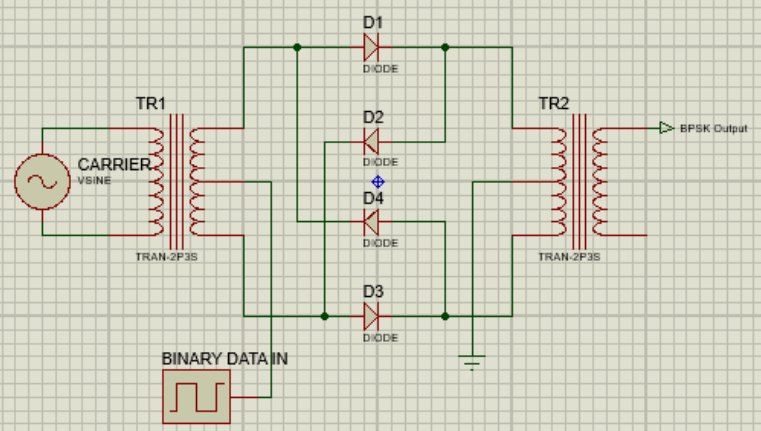

- Above is a BPSK modulator which uses a balanced modulator. 

- The carrier wave is a high frequency sinusoidal wave and the binary data input waveform is a square wave of amplitudes +1 V and -1 V corresponding to binary values 1 and 0 respectively. 

- The diodes control the "orientation" of the sine wave that is passed through the transformer TR2. When the binary data input is +1 V, the BPSK output is equal to the carrier wave, or has no phase difference. When the binary data input is - 1 V, the BPSK output and the carrier wave will have a 180-degree phase difference, hence the modulation scheme "BPSK".

- The simulation will assume the transformers TR1 and TR2 specifications to be 1:1 and that there is no voltage drop across the diodes. Hence only the phase of the waveforms shall change.

- Below are the expected waveforms (from [What is Phase Shift Keying (PSK)? BPSK modulation, BPSK demodulation, advantages, disadvantages and applications of PSK - Electronics Coach](https://electronicscoach.com/phase-shift-keying.html)):

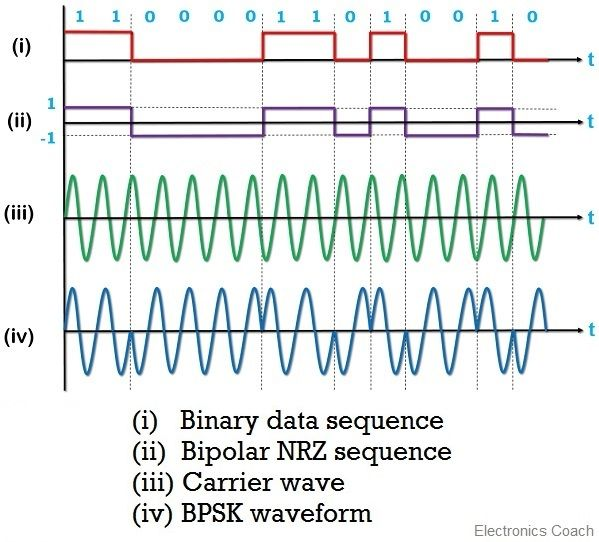

## BPSK modulator (No graphing of the waveforms)

- Scheme for generating the complex envelope is updated to match that of the built in function.

- Simulation without graphing the waveforms can accommodate more input bits since plotting requires 10k times more samples.

### Model the binary data

clear
nbits = 1e6;
bits = randi([0 1], 1, nbits)

bits =      1     1     0     0     0     1     0     0     0     1     0     1     0     1     1     0     0     0     1     0     1     0     1     0     1     0     0     1     1     1     1     0     1     0     0     0     0     1     1     1     1     0     0     1     1     0     1     0     1     0


### Generate the complex envelope

cmplx_env = zeros(size(bits));
for i = 1 : length(bits)
    switch(bits(i))
        case 1
            cmplx_env(i) = -1;
        case 0
            cmplx_env(i) = 1;
        otherwise
            error("Error in bit generation")
    end
end
cmplx_env = complex(cmplx_env)

cmplx_env =   -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i


### Add white Gaussian noise to the complex envelope

SNR = 30;   
noise_cmplx_env = awgn(cmplx_env, SNR)

noise_cmplx_env =   -1.0151 + 0.0086i  -0.9679 + 0.0555i   1.0077 - 0.0212i   1.0209 - 0.0204i   0.9891 + 0.0262i  -0.9869 + 0.0181i   1.0014 - 0.0146i   0.9612 - 0.0064i   1.0647 - 0.0132i  -0.9445 - 0.0174i   0.9919 - 0.0002i  -1.0085 - 0.0454i   1.0447 + 0.0034i  -1.0037 + 0.0235i  -1.0011 + 0.0189i   0.9743 - 0.0085i   0.9969 - 0.0053i   0.9971 + 0.0113i  -1.0006 - 0.0073i   1.0580 + 0.0105i  -0.9987 - 0.0219i   0.9982 + 0.0059i  -1.0501 - 0.0328i   0.9810 - 0.0103i  -1.0051 - 0.0017i   0.9833 - 0.0080i   1.0194 - 0.0135i  -1.0345 + 0.0193i  -1.0172 + 0.0122i  -1.0669 - 0.0134i  -1.0403 - 0.0523i   0.9723 - 0.0200i  -1.0686 - 0.0018i   0.9585 - 0.0073i   0.9676 + 0.0254i   0.9941 - 0.0108i   1.0116 + 0.0280i  -1.0087 + 0.0161i  -0.9644 - 0.0049i  -0.9701 - 0.0450i  -1.0388 - 0.0241i   1.0010 + 0.0063i   0.9840 - 0.0115i  -0.9981 - 0.0114i  -1.0048 + 0.0284i   1.0443 + 0.0255i  -1.0336 - 0.0013i   1.0338 + 0.0046i  -0.9663 - 0.0479i   1.0489 + 0.0412i


### Plot the BPSK constellation diagram

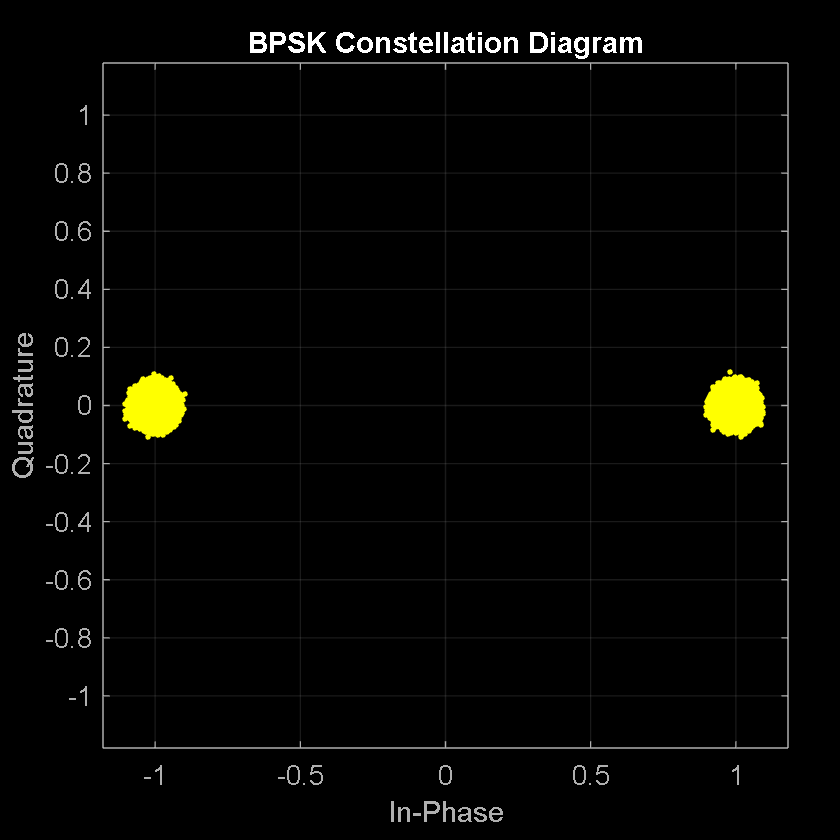

clf
figure
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Recover the bits from the noisy BPSK-modulated signal

recovered_bits = zeros(size(bits));
for i = 1 : length(noise_cmplx_env)
    if real(noise_cmplx_env(i)) < 0
        recovered_bits(i) = 1;
    elseif real(noise_cmplx_env(i)) >= 0 
        % do nothing since array is already zeros
    else
        error("Error in complex envelope generation")
    end
end
recovered_bits

recovered_bits =      1     1     0     0     0     1     0     0     0     1     0     1     0     1     1     0     0     0     1     0     1     0     1     0     1     0     0     1     1     1     1     0     1     0     0     0     0     1     1     1     1     0     0     1     1     0     1     0     1     0


### Compute for the bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("For SNR of " + num2str(SNR) + ", the BPSK modulation system produced " + num2str(number) + ...
    " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

For SNR of 30, the BPSK modulation system produced 0 number of bits in error. Resulting BER is 0 percent.

## Replication of BPSK using built-in MATLAB functions

### Generate the complex envelope using the pskmod() function

complex_envelope = pskmod(bits, 2)

complex_envelope =   -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i


### Add white Gaussian noise to the modulated waveform

noise_complex_envelope = awgn(complex_envelope, SNR)

noise_complex_envelope =   -1.0036 + 0.0020i  -0.9763 + 0.0090i   1.0224 + 0.0129i   1.0238 - 0.0163i   0.9736 + 0.0104i  -0.9955 - 0.0204i   1.0184 + 0.0009i   1.0203 + 0.0309i   0.9934 - 0.0453i  -0.9809 + 0.0430i   1.0632 - 0.0073i  -0.9969 + 0.0387i   1.0136 + 0.0156i  -1.0418 - 0.0299i  -1.0007 + 0.0173i   0.9744 - 0.0040i   1.0016 + 0.0360i   1.0156 + 0.0441i  -0.9945 + 0.0372i   1.0391 + 0.0091i  -0.9987 + 0.0120i   0.9461 + 0.0055i  -0.9986 + 0.0134i   0.9767 + 0.0056i  -1.0187 - 0.0027i   1.0200 + 0.0219i   1.0079 - 0.0059i  -1.0518 + 0.0022i  -1.0162 - 0.0127i  -0.9821 + 0.0221i  -1.0061 - 0.0124i   0.9832 - 0.0133i  -0.9811 + 0.0090i   1.0074 - 0.0137i   1.0094 + 0.0167i   0.9868 - 0.0185i   0.9961 - 0.0146i  -0.9698 + 0.0286i  -0.9595 + 0.0091i  -1.0109 + 0.0089i  -1.0142 - 0.0001i   1.0014 - 0.0169i   0.9627 - 0.0087i  -0.9819 + 0.0163i  -0.9884 + 0.0359i   1.0375 - 0.0234i  -1.0271 - 0.0079i   0.9830 + 0.0305i  -1.0109 - 0.0283i   0.9930 - 0.0100i


### Plot the BPSK constellation diagram

clf
figure
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Recover the bits 

recovered_bits = pskdemod(noise_cmplx_env, 2)

recovered_bits =      1     1     0     0     0     1     0     0     0     1     0     1     0     1     1     0     0     0     1     0     1     0     1     0     1     0     0     1     1     1     1     0     1     0     0     0     0     1     1     1     1     0     0     1     1     0     1     0     1     0


### Compute for the bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("For SNR of " + num2str(SNR) + ", the BPSK modulation system produced " + num2str(number) + ...
    " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

For SNR of 30, the BPSK modulation system produced 0 number of bits in error. Resulting BER is 0 percent.

clear

## Simulation of BPSK modulator

### Model the carrier

fc = 1e6;
Ac = 1;

### Model the binary data

% nbits = 8;
% bits = randi([0 1], 1, nbits)
bits = [1 0 1 0 1 0 0 1]

bits =      1     0     1     0     1     0     0     1


### Generate the binary waveforms

bin = zeros(size(bits));
binwave = [];
NRZ = [];
for i = 1 : length(bin)
    if bits(i) == 1
        bin(i) = 1;
        NRZ = [NRZ ones(1, fc)];
        binwave = [binwave ones(1, fc)];
    elseif bits(i) == 0
        bin(i) = -1;
        NRZ = [NRZ -ones(1, fc)];
        binwave = [binwave zeros(1, fc)];
    end
end

### Generate the carrier waveform

T = linspace(0, length(bin)/fc, length(bin)*fc);
carrier = Ac.*sin(2*pi*fc*T);

### Generate the BPSK-modulated waveform

BPSK = [];
for i = 1 : length(bin)
    if NRZ((i-1)*fc + 1) >= 0
        BPSK = [BPSK carrier(1 : fc)];
    elseif NRZ((i-1)*fc + 1) < 0
        BPSK = [BPSK -carrier(1 : fc)];
    end
end

### Display all generated waveforms

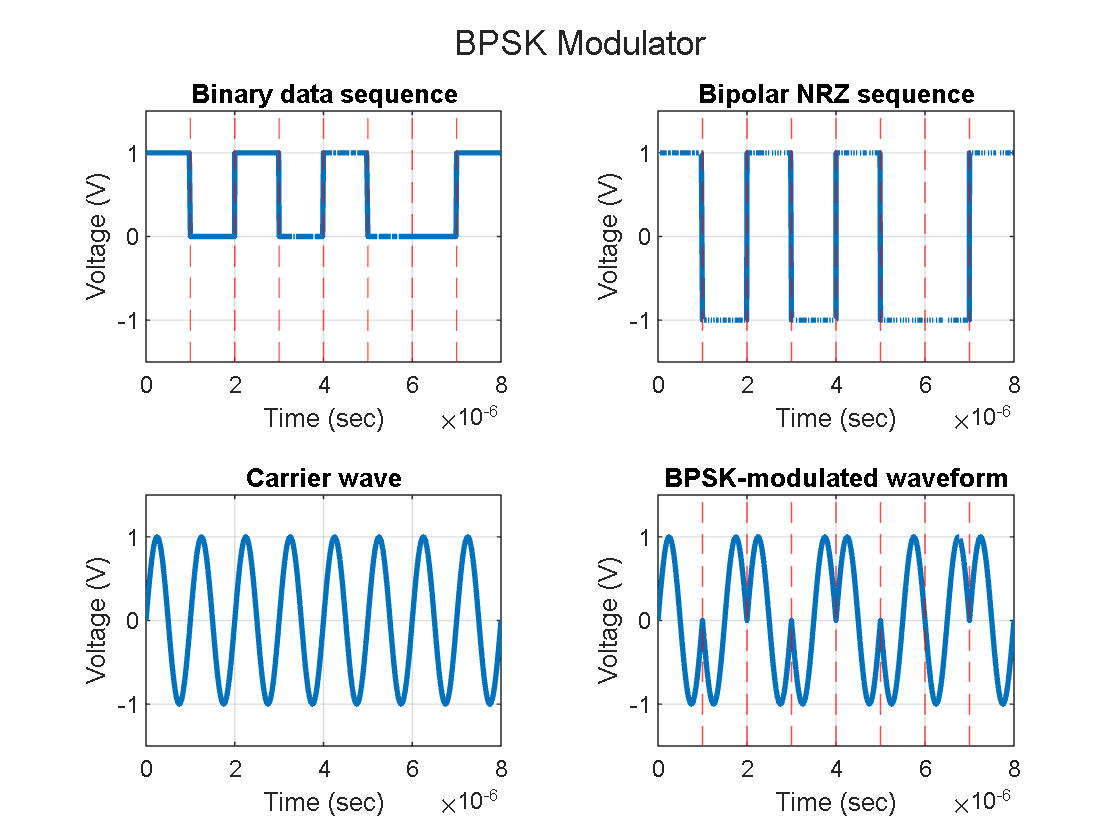

clf
figure
tiledlayout(2, 2)

nexttile % Binary data sequence
plot(T, binwave, LineWidth=2)
title("Binary data sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim((max(abs(binwave))*(3/2)).*[-1 1])
for i = 1 : length(bin)-1, xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile % Bipolar NRZ sequence
plot(T, NRZ, LineWidth=2)
title("Bipolar NRZ sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim([-2 2])
ylim((max(abs(NRZ))*(3/2)).*[-1 1])
for i = 1 : length(bin)-1, xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile % Carrier wave
plot(T, carrier, LineWidth=2)
title("Carrier wave")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim((Ac*(3/2)).*[-1 1])
grid on

nexttile % BPSK-modulated waveform
plot(T, BPSK, LineWidth=2)
title("BPSK-modulated waveform")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim((Ac*(3/2)).*[-1 1])
for i = 1 : length(bin)-1, xline(i/fc, LineStyle='--', Color='red'); end
grid on

sgtitle("BPSK Modulator")